# 2D-2Link-Manipulator Inverse Kinematics

clear;clc;
options = optimset('Display','off');
l1 = 7; l2 = 5;

## IK

theta0 = [0.1;0.1];
target = [6;4];
[theta,val,flag] = fsolve(@(theta) target-manipulator_kinematics(l1,l2,theta),theta0,options);

## Plot

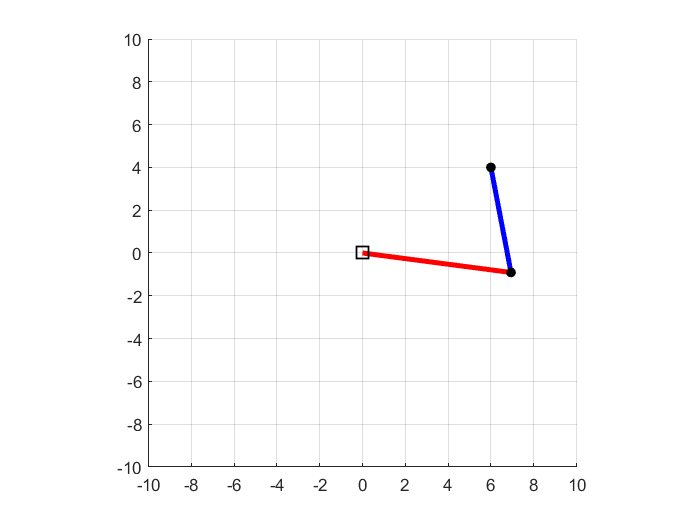

figure(1);
clf;
grid on;
hold on;
plot_manipulator;
hold off;

## Trajectory

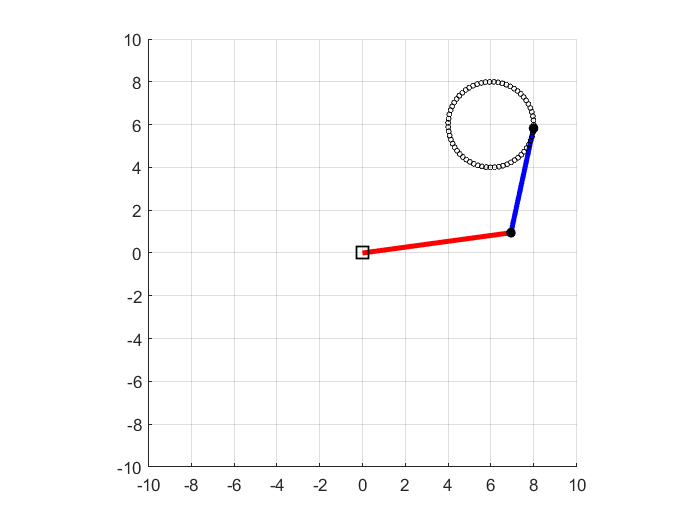

ang = 0:0.1:2*pi;
center = [6;6];
r = 2;
eef_points = [];
figure(2);
for k=ang
    target_c = center + [r*cos(k);r*sin(k)];
    eef_points = [eef_points target_c];
    [theta,val,flag] = fsolve(@(theta) target_c-manipulator_kinematics(l1,l2,theta),theta0,options);
    clf;
    figure(2);
    grid on;
    hold on;
    plot_manipulator;
    for n=1:size(eef_points,2)
        eef_point = eef_points(:,n);
        plot(eef_point(1), eef_point(2), 'o', 'MarkerSize', 3, 'Color', 'black');
    end
    drawnow;
    hold off;    
%     theta0 = theta; % Make IC equal to previous solution for faster convergence.
end